clear variables     % Erase all existing variables
clc;                % Clear the command window.
close all           % Close all figures

% Add folders for libraries
addpath(genpath('./lib/'));

workspace;          % Make sure the workspace panel is showing.
fontSize = 25;
chopmark = false;     % Define whether larger signal is chopped to improve CCF in the comparison
plot_figures = true; % To plot figures if true
display_figure = false; % Display plotted figres if true
save_figure = true; % Save plotted figure if true

dir_data = './data';
group_names = ["Group A", "Group B", "Group C"];

dir_img = './figures/';
if ~exist(dir_img, 'dir')
    mkdir(dir_img);
end

## Start

tic %starts the clock
beep on %

Get filenames stored in the data folder and read the data from each file

files = {dir(fullfile(dir_data, '*.stl')).name};

n_files = size(files,2);

Apts = cell(1, n_files);
Acon = cell(1, n_files);

for file_idx = 1:n_files
    path_cur_raw_data = fullfile(dir_data, files(file_idx));
    cur_raw_data = importdata(path_cur_raw_data{1});
    
    Apts{file_idx} = cur_raw_data.Points;
    Acon{file_idx} = cur_raw_data.ConnectivityList;
end

## Initialize variables

CompZ        = [];            % Matrix for the z signal of both marks
marksize     = zeros(2,n_files);    % Matrix for the width and length of each mark
meanXCorrs   = zeros(1,n_files);    % Matrix for mean x correlation of each mark
maxXCorrs    = zeros(1,n_files);    % Matrix for max x correlation of each mark
minXCorrs    = zeros(1,n_files);    % Matrix for min x correlation of each mark
STDXCorrs    = zeros(1,n_files);    % Matrix for STD of x correlation of each mark
meaSuperZs   = zeros(1,n_files);    % Matrix for Mean of all Z-Signals of each mark
meanlags     = zeros(1,n_files);    % Matrix for movement necessary for aligning the signals each mark
meanwaviness = zeros(1,n_files);
deltaYs      = zeros(1,n_files);    % Matrix for distance between two points on the y-scale
spans        = zeros(1,n_files);    % Matrix for span
Rzs          = zeros(1,n_files);    % Matrix for Rz
Rmaxs        = zeros(1,n_files);    % Matrix for Rz

signallengthmms = zeros(1,n_files); % Added - Archili
signalwidthmms = zeros(1,n_files); % Added - Archili
deltaXs = zeros(1,n_files); % Added - Archili
wavemeans = zeros(1,n_files);
Mark = cell(1,n_files);

## Loop

for m = 1:n_files
    % loads file name
    file = files{m};
    
    % Split up the data into Signals

    % Tool Scan Data m given as X [mm], Y [mm],
    % Each signal corresponding to a constant x-value
    [Xsignal,Ysignal,Zsignal] = getSignals(Apts{m});
    [NoY,NoX] = size(Ysignal);
    marksize(1:2,m) = [NoX; NoY];
    
    [xp,yp,zp,X,Y,Z] = getPointsGrids(Apts{m},NoX,NoY);
    
    
    %% 3D triangulated Surface Plot
    if plot_figures == true
        plot_trisurface(Acon{m},xp,yp,zp,file,display_figure,save_figure,dir_img)
        
        %% Gridded Surface Plot
        plot_gridsurface(X,Y,Z,file,display_figure,save_figure,dir_img);
    end
    
    
    % distance between two point on the y-scale
    deltaY               = abs(Ysignal(1,1) - Ysignal(2,1));
    deltaYs(1,m)         = deltaY;
    signallengthmms(1,m) = deltaY*NoY;

    % distance between two point on the x-scale
    deltaX               = abs(Xsignal(1,1) - Xsignal(1,2))  ;
    deltaXs(1,m)         = deltaX;
    signalwidthmms(1,m)  = deltaX*NoX;
    
    if plot_figures == true
        %% Plot 10 Signals (not preprocessed)
        NoOfPlots = min(10, size(Zsignal, 2));
        
        str = strcat(num2str(NoOfPlots),' signals - raw : ', file);
        plot_selected_signals(Ysignal, Zsignal, str, NoOfPlots,display_figure,save_figure,dir_img)
    end
    
    %% Roughness
    
    % roughness is calculated for all signal (before smoothing) and then
    % averaged; this calculation can be used for optional checks
    [Rz,Rmax]  = roughness(Zsignal,deltaY);
    Rzs(1,m)   = Rz;
    Rmaxs(1,m) = Rmax;
    
    
    %%Smoothing Signals
    % removing coarse features by removing moving average
    span     = 0.3;
    wavemean = (0);       %Dummy
    Zsmooth  = Zsignal;

    for ix=1:NoX
        waviness = smooth(Zsignal(:,ix),span,'loess');
        Zsmooth(:,ix) = Zsmooth(:,ix) - waviness;
        % smooth(matrix,span) sets the span of the moving average to span.
        wavemean = wavemean + mean(abs(waviness));
    end
    Data_smooth    = Zsmooth;        % smoothed data
    wavemean       = wavemean/NoX;   % Sum of waviness per no of signals
    wavemeans(1,m) = wavemean;       % spans for smoothing of signal 1 and 2
    spans(1,m)     = span;           % spans for smoothing of signal 1 and 2
    
    if plot_figures == true
        NoOfPlots = min(10, size(Ysignal, 2));
        myfig = figure(25);
        
        str = strcat(num2str(NoOfPlots),' signals - smoothed : ', file);
        plot_selected_signals(Ysignal, Zsmooth, str, NoOfPlots,display_figure,save_figure,dir_img)
    end
    
    %% Aligning Signals
    
    %  Algining the signatures using normalized cross correlation
    Zalign = Zsmooth;
    Yalign = Ysignal;

    maxlag   = round(0.3*length(Zalign));  %maximum lag for cross correlation
    Corrcfs  = zeros((NoX-1),1);
    lag_all  = zeros((NoX-1),1);
    movement = zeros((NoX-1),1);

    counter=0;
    Y1=Yalign(:,1);
    Z1=Zalign(:,1);

    for  ix=2:NoX

        Y2=Yalign(:,ix);
        Z2=Zalign(:,ix);

        [r,lags] = xcorr(Z1,Z2,maxlag,'coeff');
        % cross correlation: 'coeff' — Normalizes the sequence so that
        % the autocorrelations at zero lag equal 1
        [Corrcf,I]=max(abs(r)); %max correlation coefficient
        lag_max_Corrcf=lags(I); %lag of signatures at maximum x correlation


        % if loop to align signals
        if any(lag_max_Corrcf < 0)           %Singature 2 follows Signature 1
            lagx=lags(I)*(-1);
            Z2(1:end-lagx)=Z2(lagx+1:end);
            Z2(end-lagx+1:end)=ones(lagx,1)*mean(Z2);

        else
            lagx=lags(I);               %Singature 1 follows Signature 2
            Z2(lagx+1:end)=Z2(1:end-lagx);
            Z2(1:lagx)=ones(lagx,1)*mean(Z2); % fills with mean Z2

        end

        Yalign(:,ix)=Y2;
        Zalign(:,ix)=Z2;
        Zs4now=Zalign(:,2:ix);
        Z1=mean(Zs4now,2);

        counter=counter+1;
        lag_all(counter,1)=lag_max_Corrcf;
        movement(counter,1)=lagx;
        Corrcfs(counter,1)=Corrcf;

    end

    meanXCorr=mean(Corrcfs)
    maxXCorr=max(Corrcfs);
    minXCorr=min(Corrcfs);
    STDXCorr=std(Corrcfs);
    meanXCorrs(1,m)=meanXCorr;          % saves mean X correlation for export
    maxXCorrs(1,m)=maxXCorr;            % saves max X correlation for export
    minXCorrs(1,m)=minXCorr;            % saves min X correlation for export
    STDXCorrs(1,m)=STDXCorr;            % saves STD X correlation for export
    % lag_alls(:,m)=lag_all; %RSP
    Smoothed_filtered_Aligned_Data = Zalign;
    allmovement=sum(movement)
    % all movement of signals performed for the alignement (shortens signal length)
    meanlags(1,m)=allmovement/NoX;
    % saves allmovements for export

    if plot_figures == true
        NoOfPlots = min(10, size(Ysignal,2));
        titstr = strcat(num2str(NoOfPlots),' signals - aligned : ', file);
        plot_selected_signals(Ysignal, Zalign, titstr, NoOfPlots,display_figure,save_figure,dir_img)
        
        %% Plot moving average
        
        % before and after picture of first signal
        Zsignals = [Zsignal(:,1),Zsmooth(:,1),smooth(Zsignal(:,1),span,'loess')];
        titstr = ['First Signal: ', file];
        legstr = {'Original Signal', 'Smoothed Signal', 'Moving Average'};
        plot_signals(Ysignal(:,1), Zsignals, titstr, legstr,display_figure,save_figure,dir_img)
    
        % ten signals after smoothing
        titstr = ['First ten signals smoothed: ', file];
        plot_signals(Ysignal(:,1:NoOfPlots), Zsmooth(:,1:NoOfPlots), titstr, '',display_figure,save_figure,dir_img)
    
        NoOfPlots = min(10, size(Ysignal,2));
        titstr = strcat(num2str(NoOfPlots),' spaced signals - smoothed: ', file);
        plot_selected_signals(Yalign, Zalign, titstr, NoOfPlots,display_figure,save_figure,dir_img)
       
        
        %% Plot Mean Correlation Coefficient
        
        myfig = figure();
        if display_figure == false
            set(myfig, 'Visible', 'off');
        end
        
        
        plot(Corrcfs)
        
        if save_figure == true
            saveas(myfig, [dir_img, 'mean_correlation_coefficient', file, '.png']);
        end
        hold on
    end

    NoCorr    = length(Corrcfs);
    corrline  = ones(NoCorr,1)*meanXCorr;
    corrlineX = (1:NoCorr)';
    
    
    if plot_figures == true
        plot(corrlineX,corrline)
        
        ylim([0 1])
        ylabel('Cross Correlation')
        xlabel('Signal 1 vs Signal N')
        title(['Aligning: Correlation coefficient: ' num2str(meanXCorr) {} file])
        legend('Correlation Coefficient', 'Mean')
        hold off
    end

    clear NoCorr
    drawnow
    
    if plot_figures == true
        %% Plot aligned signals
        
        % First ten signals after alignement
        titstr = ['First ten signals aligned: ', file];
        plot_signals(Ysignal(:,1:NoOfPlots), Smoothed_filtered_Aligned_Data(:,1:NoOfPlots), titstr, '',display_figure,save_figure,dir_img)
    
        titstr = ['All signals - raw: ', file];
        plot_signals(Ysignal, Zsmooth, titstr, '',display_figure,save_figure,dir_img);
    
        titstr = ['All signals - aligned: ', file];
        plot_signals(Ysignal, Smoothed_filtered_Aligned_Data, titstr, '',display_figure,save_figure,dir_img);
    end
    
    %% Merge Signals
    
    % Merging the aligned signals to one signal per mark
    Ymean = mean(Yalign,2);
    Zmean = mean(Smoothed_filtered_Aligned_Data,2);
    Mark{m} = Zmean;
    
    if plot_figures == true
        %% Plot merged Signals
        %First signal original and smoothed and the extracted (mean) signature of
        %the mark
        Zsignals = [Zsignal(:,1),Zsmooth(:,1),Zmean, smooth(Zsignal(:,1),span,'loess')];
        titstr = ['Resulting First Signal per Mark: ', file];
        legstr = {'Original Signal','Smoothed Signal', 'Mean Signal','Moving Average'};
        plot_signals(Ysignal(:,1), Zsignals, titstr, legstr,display_figure,save_figure,dir_img);
    end
    %% End of Slope
    fprintf('File %i / %i done \n', m, n_files);
    beep
end

meanXCorr = 0.9829

allmovement = 83

File 1 / 29 done 


meanXCorr = 0.9724

allmovement = 67

File 2 / 29 done 


meanXCorr = 0.9920

allmovement = 0

File 3 / 29 done 


meanXCorr = 0.9005

allmovement = 53

File 4 / 29 done 


meanXCorr = 0.9101

allmovement = 171

File 5 / 29 done 


meanXCorr = 0.9532

allmovement = 16

File 6 / 29 done 


meanXCorr = 0.9050

allmovement = 48

File 7 / 29 done 


meanXCorr = 0.9694

allmovement = 64

File 8 / 29 done 


meanXCorr = 0.9357

allmovement = 0

File 9 / 29 done 


meanXCorr = 0.9823

allmovement = 91

File 10 / 29 done 


meanXCorr = 0.9063

allmovement = 35

File 11 / 29 done 


meanXCorr = 0.9345

allmovement = 28

File 12 / 29 done 


meanXCorr = 0.9007

allmovement = 18

File 13 / 29 done 


meanXCorr = 0.9756

allmovement = 56

File 14 / 29 done 


meanXCorr = 0.9798

allmovement = 79

File 15 / 29 done 


meanXCorr = 0.9615

allmovement = 35

File 16 / 29 done 


meanXCorr = 0.8617

allmovement = 7

File 17 / 29 done 


meanXCorr = 0.9742

allmovement = 80

File 18 / 29 done 


meanXCorr = 0.9894

allmovement = 87

File 19 / 29 done 


meanXCorr = 0.9808

allmovement = 0

File 20 / 29 done 


meanXCorr = 0.9730

allmovement = 87

File 21 / 29 done 


meanXCorr = 0.9865

allmovement = 94

File 22 / 29 done 


meanXCorr = 0.9784

allmovement = 70

File 23 / 29 done 


meanXCorr = 0.8010

allmovement = 65

File 24 / 29 done 


meanXCorr = 0.9805

allmovement = 87

File 25 / 29 done 


meanXCorr = 0.9554

allmovement = 70

File 26 / 29 done 


meanXCorr = 0.8898

allmovement = 18

File 27 / 29 done 


meanXCorr = 0.9823

allmovement = 78

File 28 / 29 done 


meanXCorr = 0.9045

allmovement = 39

File 29 / 29 done 




%% Calculating correlation matrix for n files
correlation_matrix = zeros(n_files);

for file_1_idx = 1:n_files
    for file_2_idx = 1:n_files
        correlation_matrix(file_1_idx, file_2_idx) = compare_marks(Mark{file_1_idx}, Mark{file_2_idx}, true);
        correlation_matrix(file_2_idx, file_1_idx) = correlation_matrix(file_1_idx, file_2_idx);
    end
end

% Plot correlation matrix
plot_correlation_matrix(correlation_matrix, files, true(1, n_files), "Correlation Matrix - Whole Dataset",display_figure,save_figure,dir_img);

    "./figures/"    "Correlation Matrix - Whole Dataset"    ".png"



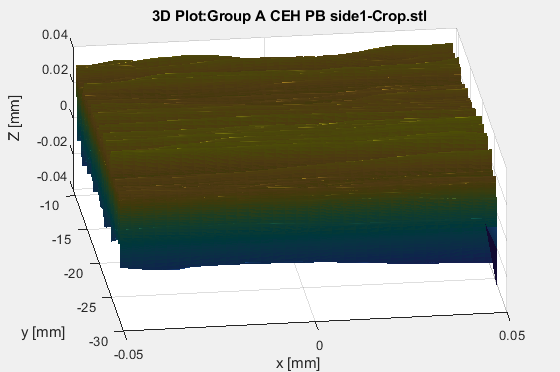


% Histograms of the correlation matrices are plotted in this figure (Figure 1)
myfig = figure(1);

selector_helper = true(size(correlation_matrix));

% Correlations with excluded main diagonal and duplicates
hist_values = correlation_matrix(triu(selector_helper,1))';

    "Hist values n whole: "    "406"



h = histogram(hist_values,'DisplayName', strcat('Whole data (','\mu=',num2str(round(mean(hist_values),2)),' \sigma=',num2str(round(var(hist_values),2)), ' \sigma^2=',num2str(round(std(hist_values),2)), ')'));
hold on
h.FaceAlpha = 0.7;

% Plotting histograms and correlation matrices for groups
for group_idx = 1:size(group_names,2)
    group_data_idxs = cellfun(@(x) contains(x, group_names(group_idx)), files);
    
    % If there is data for the current group
    if sum(group_data_idxs) > 0
        % Plotting correlation matrix
        plot_correlation_matrix(correlation_matrix, files, group_data_idxs, "Correlation Matrix - Group: " + group_names(group_idx),display_figure,save_figure,dir_img);
        
        % Plotting histograms
        selected_matrix = correlation_matrix(group_data_idxs, group_data_idxs);
        selector_helper = true(sum(group_data_idxs));
        
        myfig = figure(1);
        if display_figure == false
            set(myfig, 'Visible', 'off');
        end
        
        hist_values = selected_matrix(triu(selector_helper,1))';
        hold on
        h = histogram(hist_values,'DisplayName', strcat(group_names(group_idx), ' (','\mu=',num2str(round(mean(hist_values),2)),' \sigma=',num2str(round(var(hist_values),2)), ' \sigma^2=',num2str(round(std(hist_values),2)), ')'));
        h.FaceAlpha = 0.7;
    else
        warning(strcat("No Data fpr the group: ", group_names(group_idx)));
    end
end

    "./figures/"    "Correlation Matrix - Group_ Group A"    ".png"



    "Hist values n group "    "Group A"    " :"    "136"



    "./figures/"    "Correlation Matrix - Group_ Group B"    ".png"



    "Hist values n group "    "Group B"    " :"    "66"



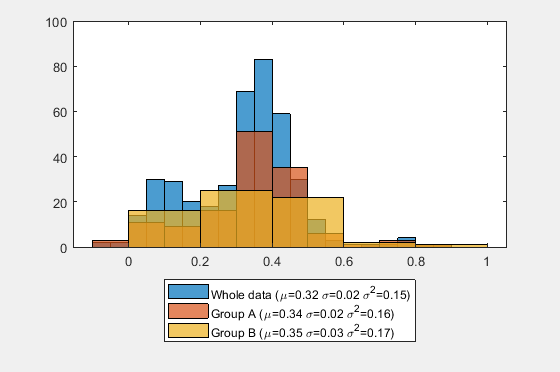


hold off
legend('location', "southoutside")

% Saving figure for the histograms
myfig = figure(1);

if save_figure == true
    saveas(myfig, [dir_img, 'correlations_histogram', '.png']);
end



% Write results to table
T = array2table(correlation_matrix, 'RowNames', files, 'VariableNames', files);
writetable(T, 'correlation_matrix.xlsx', 'WriteRowNames', true);


rmpath(genpath('./lib/'));